# Optimization Fundamentals - Kmedoids. 

#### Francesco Rinaudo and Michele Pierro

The datasets we will work on and perform the appropriate checks on are .cvs files named as follows.

Insert one of the following files into the input table: 

- dataset.csv

- dataset_out.csv

**In this code, a fixed random seed is used to guarantee the reproducibility of the outputs.**

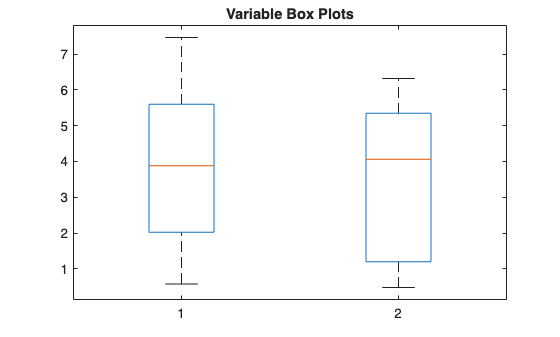

rng(50)  % SEED
% Reading and initialization of data
ipttable = input('Inserici la tabella >>> ','s');

Xt = readtable(ipttable, "Delimiter", ',');
rownames = "obs_" + string(1:height(Xt));
Xt.Properties.RowNames = rownames';

% Convert to a numerical matrix for calculations.
X = table2array(Xt);
[n,p] = size(X);

% Range of possible values of k
k_min = 1; 
k_max = 10; 

% We check for the presence of outliers in the dataset.
figure('Name','BoxPlot')
figure; boxplot(X);
title('Variable Box Plots');


if ipttable == "dataset.csv"
    fprintf(['=== OUTLIER ANALYSIS ===\n\n' ...
    'The boxplots do not reveal any evident outliers, as no observations ' ...
    'appear outside the whiskers.\n' ...
    'Both variables show a fairly regular distribution and a moderate level ' ...
    'of dispersion.\n' ...
    'This suggests that the dataset does not contain extremely anomalous ' ...
    'observations and, therefore, k-means and k-medoids are expected to ' ...
    'produce similar clustering results.\n' ...
    'Under these conditions, the robustness advantage of k-medoids over ' ...
    'k-means is less pronounced.\n\n']);
elseif ipttable == "dataset_out.csv"
    fprintf(['=== OUTLIER ANALYSIS ===\n\n' ...
        'The boxplots clearly reveal the presence of several outliers in both variables,\n' ...
        'as many observations lie beyond the upper whiskers.\n' ...
        'These extreme values significantly increase the variability of the dataset\n' ...
        'and may influence the position of the centroids computed by k-means.\n' ...
        'In contrast, k-medoids is expected to be more robust, since medoids are\n' ...
        'actual observations and are less sensitive to the presence of outliers.\n' ...
        'Therefore, this dataset provides a suitable scenario to compare the\n' ...
        'robustness of k-medoids and k-means.\n\n']);
end 

=== OUTLIER ANALYSIS ===

The boxplots do not reveal any evident outliers, as no observations appear outside the whiskers.
Both variables show a fairly regular distribution and a moderate level of dispersion.
This suggests that the dataset does not contain extremely anomalous observations and, therefore, k-means and k-medoids are expected to produce similar clustering results.
Under these conditions, the robustness advantage of k-medoids over k-means is less pronounced.




% OPTIMIZATION PROBLEM FORMULATION
fprintf(['=== OPTIMIZATION PROBLEM FORMULATION ===\n\n' ...
    'Given a dataset X = {x_1, ..., x_n} of n observations,\n' ...
    'the k-medoids problem seeks to find a set of k medoids\n' ...
    'M = {m_1, ..., m_k} subset of X (i.e., actual observations)\n' ...
    'that minimizes the total within-cluster dissimilarity:\n\n' ...
    '   min  sum_{i=1}^{n} d(x_i, m_{c(i)})\n' ...
    '    M\n\n' ...
    'where:\n' ...
    '  - M subset X        : medoids are constrained to be actual data points\n' ...
    '  - c(i) = argmin_j d(x_i, m_j) : cluster assignment of observation x_i\n' ...
    '  - d(x_i, m_j) = ||x_i - m_j||^2 : squared Euclidean distance\n\n' ...
    'Decision variables:\n' ...
    '  - M = {m_1,...,m_k}           : set of k medoids (indices into X)\n' ...
    '  - c : {1,...,n} -> {1,...,k}  : assignment function\n\n' ...
    'Objective function:\n' ...
    '  - Total cost = sum of squared distances of each point\n' ...
    '    to its assigned medoid\n\n' ...
    'Assignment structure:\n' ...
    '  - Each observation x_i is assigned to the nearest medoid:\n' ...
    '    c(i) = argmin_j d(x_i, m_j)\n\n' ...
    'Key difference from k-means:\n' ...
    '  - k-means allows centroids to be ANY point in R^p (arithmetic mean)\n' ...
    '  - k-medoids enforces M subset X, so no outlier can pull a\n' ...
    '    medoid toward itself, making the method inherently robust\n\n']);

=== OPTIMIZATION PROBLEM FORMULATION ===

Given a dataset X = {x_1, ..., x_n} of n observations,
the k-medoids problem seeks to find a set of k medoids
M = {m_1, ..., m_k} subset of X (i.e., actual observations)
that minimizes the total within-cluster dissimilarity:

   min  sum_{i=1}^{n} d(x_i, m_{c(i)})
    M

where:
  - M subset X        : medoids are constrained to be actual data points
  - c(i) = argmin_j d(x_i, m_j) : cluster assignment of observation x_i
  - d(x_i, m_j) = ||x_i - m_j||^2 : squared Euclidean distance

Decision variables:
  - M = {m_1,...,m_k}           : set of k medoids (indices into X)
  - c : {1,...,n} -> {1,...,k}  : assignment function

Objective function:
  - Total cost = sum of squared distances of each point
    to its assigned medoid

Assignment structure:
  - Each observation x_i is assigned to the nearest medoid:
    c(i) = argmin_j d(x_i, m_j)

Key difference from k-means:
  - k-means allows centroids to be ANY point in R^p (arithmetic mean)
  - k-med

# KMEDOIDS 

%% ELBOW METHOD + PAM algorithm 
cost = zeros(k_max,1);
medoids_idx = cell(k_max,1);
inc_idx = cell(k_max,1);
cluster_idx = cell(k_max,1);

for k = k_min:k_max
    inc = sort(randperm(n,k));
    obs = inc;
    medoids = X(inc, :);
    D = zeros(n, k);
    for i = 1:n
        for j = 1:k
            D(i,j) = sum((X(i,:) - medoids(j,:)).^2);
        end
    end
    cost_best = sum(min(D, [], 2));

    improved = true;
    while improved
        improved = false;
        for m = 1:k
            for cand = 1:n
                if ismember(cand, obs)
                    continue
                end
                cand_obs = obs;
                cand_obs(m) = cand;
                cand_meds = X(cand_obs, :);

                Dcand = zeros(n, k);
                for i = 1:n
                    for j = 1:k
                        Dcand(i,j) = sum((X(i,:) - cand_meds(j,:)).^2);
                    end
                end
                [dist,~] = min(Dcand, [], 2);
                cand_cost = sum(dist);

                if cand_cost < cost_best
                    cost_best = cand_cost;
                    obs = cand_obs;
                    medoids = cand_meds;
                    improved = true;
                end
            end
        end
    end

    % Final distances and clustering
    D_final = zeros(n, k);
    for j = 1:k
        D_final(:, j) = sum((X - medoids(j,:)).^2, 2);
    end
    [~, cluster] = min(D_final, [], 2);

    cost(k) = cost_best;
    medoids_idx{k} = obs;
    cluster_idx{k} = cluster;
    inc_idx{k} = inc;

    fprintf('k = %d: cost = %.6f, medoids indices = [%s], inc_start = [%s]\n', ...
        k, cost_best, sprintf('%d ', obs), sprintf('%d ', inc));
end

k = 1: cost = 837.048543, medoids indices = [49 ], inc_start = [50 ]
k = 2: cost = 579.198695, medoids indices = [80 55 ], inc_start = [23 26 ]
k = 3: cost = 295.012728, medoids indices = [85 65 100 ], inc_start = [38 40 98 ]
k = 4: cost = 100.972973, medoids indices = [43 80 65 85 ], inc_start = [31 41 75 77 ]
k = 5: cost = 31.229337, medoids indices = [65 85 80 72 25 ], inc_start = [15 35 88 95 100 ]
k = 6: cost = 28.107564, medoids indices = [65 80 72 59 85 97 ], inc_start = [32 38 49 56 66 88 ]
k = 7: cost = 23.442952, medoids indices = [97 72 61 56 65 59 80 ], inc_start = [6 32 53 56 65 92 96 ]
k = 8: cost = 17.623167, medoids indices = [51 72 56 73 61 97 80 59 ], inc_start = [18 38 44 70 71 88 92 99 ]
k = 9: cost = 14.869216, medoids indices = [80 72 59 73 61 97 51 58 56 ], inc_start = [22 41 59 65 66 69 75 84 85 ]
k = 10: cost = 12.802443, medoids indices = [80 59 61 97 75 58 72 73 51 56 ], inc_start = [13 24 29 38 44 58 72 77 79 89 ]


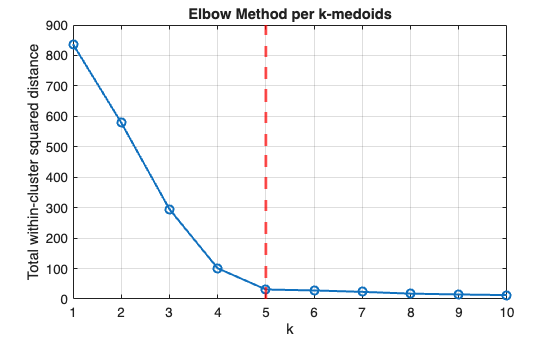


% Plot Elbow
figure('Name','Elbow k-medoids');
plot(k_min:k_max, cost(k_min:k_max), '-o', 'LineWidth', 1.5);
xlabel('k'); ylabel('Total within-cluster squared distance');
% Choose the Optimal k and
k_best = input('Select the optimal number of k >>> ');
xline(k_best,"Color",'r','LineWidth',2,'LineStyle','--')
title('Elbow Method per k-medoids');
grid on;


% Show the result 
finalMedoids = X(medoids_idx{k_best}, :);  
bestCost = cost(k_best);
obs = medoids_idx{k_best};
inc = inc_idx{k_best};
fprintf('Number of optimal k: %d\n', k_best);

Number of optimal k: 5


fprintf('Best Cost with k= %d : %f\n',k_best ,bestCost);

Best Cost with k= 5 : 31.229337


disp('Best Medoids: ')

Best Medoids: 


disp(Xt(obs,:));

                x1        x2  
              ______    ______

    obs_65    7.1437    5.8015
    obs_85    2.0376    4.9006
    obs_80    0.8631    1.1002
    obs_72    5.2885     1.188
    obs_25         4       3.2



clusters = cluster_idx{k_best};

% Check using the MATLAB k-medoids function
[~, chk_medoids] = kmedoids(X, k_best, Start=X(inc,:), Distance="sqeuclidean");
assert(isequal(sortrows(finalMedoids), sortrows(chk_medoids)),'ERROR: The implementations differ')
fprintf(['CORRECT IMPLEMENTATION:' ...
    '\nThe two outputs for the medoids match.\n\n']);

CORRECT IMPLEMENTATION:
The two outputs for the medoids match.



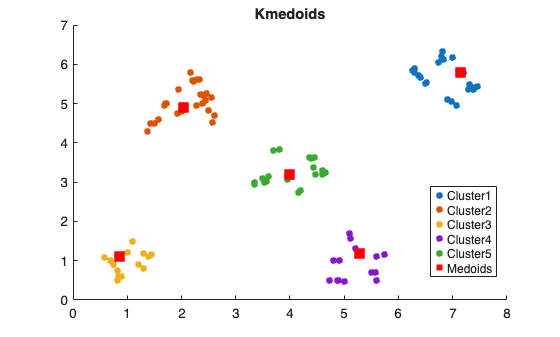



% Graph Kmedoids 
ClusterN = cellstr("Cluster" + (1:numel(unique(clusters))));

if ipttable == "dataset.csv"
    figure
    scatterplot(X, clusters, finalMedoids, ClusterN,'Medoids','Kmedoids');
elseif ipttable == "dataset_out.csv"
    figure
    scatterplot(X, clusters, finalMedoids, ClusterN, 'Medoids' ,'Kmedoids With Outliers');
end

# KMEANS 

[clusters1,centroids] = kmeans(X, k_best, Start=X(inc,:), Distance="sqeuclidean",Display="iter"); 

  iter	 phase	     num	         sum
     1	     1	     100	     280.692
     2	     1	      17	     161.264
     3	     1	      11	     127.788
     4	     1	      18	     68.9801
     5	     1	      13	     26.2043
Best total sum of distances = 26.2043


disp(centroids)

    4.0342    3.2382
    2.1135    5.0335
    6.8357    5.6708
    5.1957    0.9250
    1.0014    0.9561



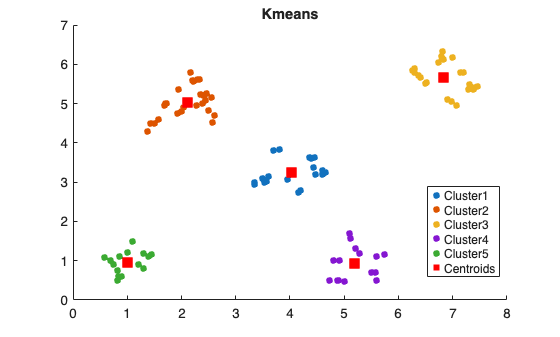


% Graph Kmeans 
ClusterN1 = cellstr("Cluster" + (1:numel(unique(clusters1))));
if ipttable == "dataset.csv"
    figure
    scatterplot(X, clusters1, centroids, ClusterN1, 'Centroids' ,'Kmeans');
elseif ipttable == "dataset_out.csv"
    figure
    scatterplot(X, clusters1, centroids, ClusterN1,'Centroids','Kmeans With Outliers');
end

% This function is intended for graphical representations
function scatterplot(X, Clust, method, numClust , type_center,figname)
gscatter(X(:,1), X(:,2), Clust);
hold on;
scatter(method(:,1), method(:,2), 100, 'r', 'filled', 's');
legend([numClust,type_center], "Location", "best");
title(figname);
hold off;
end